# Solution to the *Wine Quality: Import and Organize* exercise

## 1. Import data

Import the data in `wineQuality.csv` into a table.

data = readtable('wineQuality.csv');

This file contains chemical composition data for about 6,500 wines, as well as a quality rating and the color of the wine (red or white).

The data is available from the Machine Learning Repository at the University of California, Irvine:[https://archive.ics.uci.edu/ml/datasets/Wine+Quality](https://archive.ics.uci.edu/ml/datasets/Wine+Quality)

## 2. Convert Color to categorical

Convert the `Color` variable to a categorical data type.

data.Color = categorical(data.Color);

## 3. Extract the numeric values and calculate their *z*-score

numdata = data{:,1:end-1};
Z = zscore(numdata);

## 4. Replace any values with a *z*-score greater than 6 with `NaN`

numdata(abs(Z)>6) = NaN;
data{:,1:end-1} = numdata;

## 5. Visualize relationships between variables

Use `plotmatrix` to make scatter plots of all variables against each other. In another figure window, make a grouped scatter plot of `quality` vs. `sulphates`, grouped by `Color`.

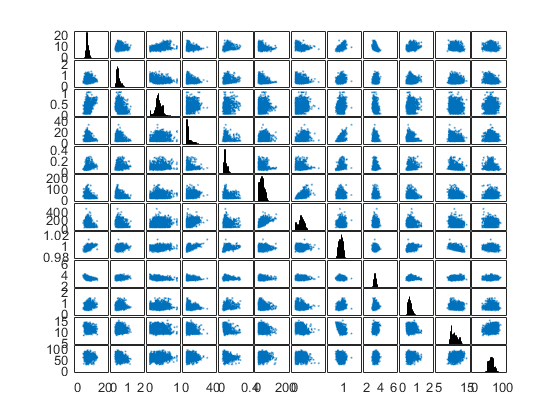

plotmatrix(numdata)

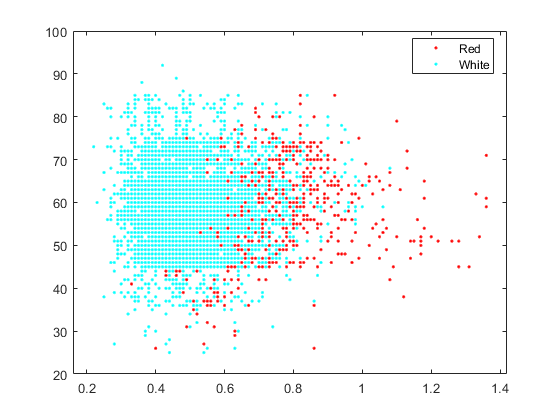

figure
gscatter(data.sulphates,data.quality,data.Color)